# Parametric Methods

**Signal length**

Try increasing the signal length slowly to see what happens in each PSD plot.

This script compares the Burg method (parametric) and the periodogram (nonparametric). The slider at the top of the script sets the length of the signal. To start, the signal only has 20 samples.

When the signal is short, you can only see the two tones with the parametric method. But once the signal is long enough, the periodogram also works. Once the signal is long enough, you may prefer the periodogram because the relative power between the two tones is more accurate.

n = 50;

Generate a signal with 2 tones at 200 and 250 Hz.

fs = 2000;
t = (0:n-1)'/fs;
x1 = sin(2*pi*200*t);
x2 = sin(2*pi*250*t);
rng default
y = x1 + x2 + 1e-2*randn(size(t));

Plot Burg PSD

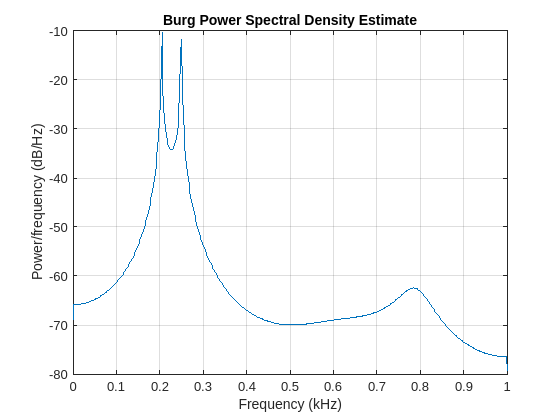

pburg(y, 8, 2^10, fs)

For comparision, plot the periodogram

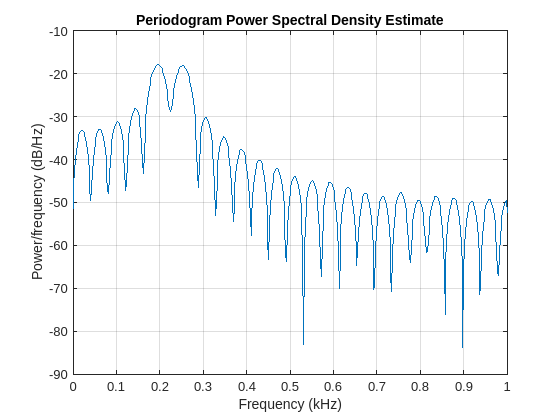

periodogram(y, [], 2^10, fs); 